% system
A = [0,1;0,0];
B1 = [-3,1,0;2,2,0];
B2 = [0;1];
C1 = [1,0];
D1 = [0,0,2];
g = 19.4;

% z(t)
C2 = [0,0;3,2];
D2 = [-2; 0];

% conditional test
C2'*D2 == 0

ans = 2×1 logical array
   1
   1


det(D2'*D2)

ans = 4

rank(ctrb(A,B2))

ans = 2

rank(obsv(A,C2))

ans = 2

B1*D1' == 0

ans = 2×1 logical array
   1
   1


det(D1*D1')

ans = 4

rank(obsv(A, C1))

ans = 2

rank(ctrb(A, B1))

ans = 2


% controller and observer
Q = icare(A,B2,C2'*C2,D2'*D2,0,eye(2),(g.^-2).*B1*B1')

Q =     6.3006    6.3437
    6.3437    8.5208


K = -inv(D2'*D2)*B2'*Q

K =    -1.5859   -2.1302



% find observer matrix
P = icare(A',C1',B1*B1',D1*D1',0,eye(2),(g.^-2).*C2'*C2)

P =    12.0731    9.2440
    9.2440   21.5925


L = -P*inv(eye(2)-(g.^-2).*Q*P)*(C1+(g.^-2).*D1*B1'*Q)'*inv(D1*D1')

L =  -144.3296
 -217.1901



max(eig(P*Q))

ans = 370.9851

g^2

ans = 376.3600

max(eig(P*Q)) < g^2

ans = logical
   1



syms s real;
W_wx = inv(eye(2)+inv(s*eye(2)-A)*B2*K*inv(s*eye(2)-A-g^(-2)*B1*B1'*Q-B2*K-L*C1)*L*C1)*inv(s*eye(2)-A)*(B1-B2*K*inv(s*eye(2)-A-g^(-2)*B1*B1'*Q-B2*K-L*C1)*L*D1);
W_wxhat = -inv(eye(2)+inv(s*eye(2)-A-g^(-2)*B1*B1'*Q-B2*K-L*C1)*L*C1*inv(s*eye(2)-A)*B2*K)*inv(s*eye(2)-A-g^(-2)*B1*B1'*Q-B2*K-L*C1)*(L*C1*inv(s*eye(2)-A)*B1+L*D1);
W_s = C2*W_wx+D2*K*W_wxhat;
size(W_s)

ans =      2     3


[N11, D11] = numden(W_s(1,1));
[N12, D12] = numden(W_s(1,2));
[N13, D13] = numden(W_s(1,3));
[N21, D21] = numden(W_s(2,1));
[N22, D22] = numden(W_s(2,2));
[N23, D23] = numden(W_s(2,3));

WN11  = coeffs(N11, 'All');
WD11  = coeffs(D11, 'All');
WN12  = coeffs(N12, 'All');
WD12  = coeffs(D12, 'All');
WN13  = coeffs(N13, 'All');
WD13  = coeffs(D13, 'All');

WN21  = coeffs(N21, 'All');
WD21  = coeffs(D21, 'All');
WN22  = coeffs(N22, 'All');
WD22  = coeffs(D22, 'All');
WN23  = coeffs(N23, 'All');
WD23  = coeffs(D23, 'All');

W = [
    tf(double(WN11), double(WD11)), tf(double(WN12), double(WD12)), tf(double(WN13), double(WD13));
    tf(double(WN21), double(WD21)), tf(double(WN22), double(WD22)), tf(double(WN23), double(WD23));
    ]

W =
 
  From input 1 to output...
                     -4.738e49 s^2 + 9.669e48 s + 1.461e49
   1:  -----------------------------------------------------------------
       1.142e46 s^4 + 1.67e48 s^3 + 6.013e48 s^2 + 7.896e48 s + 3.653e48
 
             -5.709e46 s^3 - 8.281e48 s^2 + 2.733e49 s + 5.799e49
   2:  -----------------------------------------------------------------
       1.142e46 s^4 + 1.67e48 s^3 + 6.013e48 s^2 + 7.896e48 s + 3.653e48
 
  From input 2 to output...
                     1.579e49 s^2 + 3.889e49 s + 1.461e49
   1:  -----------------------------------------------------------------
       1.142e46 s^4 + 1.67e48 s^3 + 6.013e48 s^2 + 7.896e48 s + 3.653e48
 
              7.993e46 s^3 + 1.176e49 s^2 + 3.632e49 s + 2.877e49
   2:  -----------------------------------------------------------------
       1.142e46 s^4 + 1.67e48 s^3 + 6.013e48 s^2 + 7.896e48 s + 3.653e48
 
  From input 3 to output...
                          3.158e49 s^3 + 1.461e49 s^2
   1:  --------

% ampW = bodeplot(W);
% setoptions(ampW,'FreqScale','linear','MagUnits','abs','Grid','on','PhaseVisible','off','IOGrouping','all');
% xlim([0 5]);
% 
% sinValW = sigmaplot(W);
% setoptions(sinValW,'FreqScale','linear','MagUnits','abs','Grid','on');
% xlim([0 5]);

% H_2 norm of transfer fuction
h_2 = norm(W)

h_2 = 163.8614


% H_inf norm of transfer fuction
h_inf = getPeakGain(W)

h_inf = 19.3997

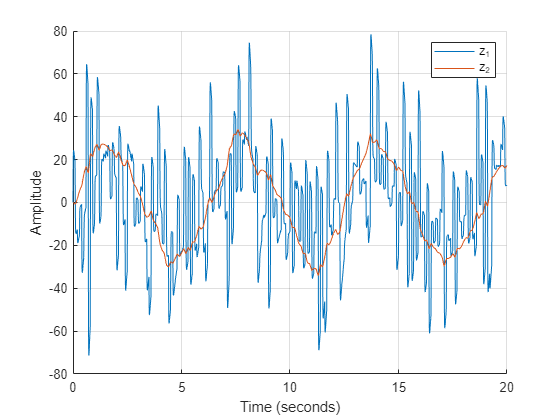


figure; %входные воздействия
grid on;
hold on;
plot(out.z.Time, out.z.Data(:,1))
plot(out.z.Time, out.z.Data(:,2))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2")

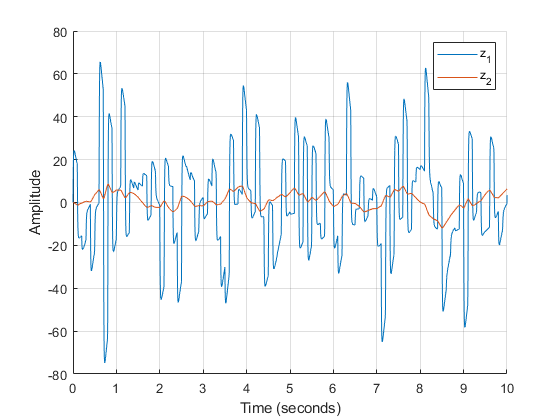

figure; %входные воздействия
grid on;
hold on;
plot(out.z1.Time, out.z1.Data(:,1))
plot(out.z1.Time, out.z1.Data(:,2))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2")
xlim([0 10])